# Data analysis of Bilbasen data set

clear;format shortG

## Load data set

opts = detectImportOptions("bilbasen_scrape.csv");
source = readtable("bilbasen_scrape.csv", opts);
preview("bilbasen_scrape.csv", opts);

Some fiddling to learn syntax

source(1:3, 1:6)

ans = 3×6 table
       Make          Model                   Configuration                 Rating         Price         Registered
    ___________    __________    ______________________________________    ______    _______________    __________

    {'Ford'   }    {'Kuga'  }    {'2,5 PHEV Vignale CVT 5d'           }     4.4      {'226.300 kr.'}    {'7/2020'}
    {'Peugeot'}    {'3008'  }    {'1,6 Hybrid First Selection EAT8 5d'}     4.4      {'199.900 kr.'}    {'2/2021'}
    {'VW'     }    {'Passat'}    {'1,4 GTE Variant DSG 5d'            }     4.3      {'239.000 kr.'}    {'5/2020'}


source(1:6, "Model")

ans = 6×1 table
        Model    
    _____________

    {'Kuga'     }
    {'3008'     }
    {'Passat'   }
    {'Kuga'     }
    {'Golf VIII'}
    {'Octavia'  }


source.Model(1:6)

ans = 6×1 cell array
    {'Kuga'     }
    {'3008'     }
    {'Passat'   }
    {'Kuga'     }
    {'Golf VIII'}
    {'Octavia'  }


source.Properties.VariableNames

ans = 1×18 cell array
    {'Make'}    {'Model'}    {'Configuration'}    {'Rating'}    {'Price'}    {'Registered'}    {'Kilometers'}    {'Fuel'}    {'Consumption'}    {'Tax'}    {'Power'}    {'Transmission'}    {'TowCapacity'}    {'PriceNew'}    {'Trunk'}    {'Width'}    {'Length'}    {'Height'}


source.Properties.VariableTypes

ans = 1×18 string array
    "cell"    "cell"    "cell"    "double"    "cell"    "cell"    "cell"    "cell"    "cell"    "cell"    "cell"    "cell"    "cell"    "cell"    "cell"    "cell"    "cell"    "cell"


## Check for empty cells in selected columns

% Get column as cell matrix (height) or table (b)
height = source.("Height");
b = source(:, "Height");

% Convert to string and look for non-empty strings
indexes_of_non_empty_cells = find(string(height) ~= "");
height = height(indexes_of_non_empty_cells);
height(1:8, :)

ans = 8×1 cell array
    {'166 cm'}
    {'162 cm'}
    {'152 cm'}
    {'166 cm'}
    {'146 cm'}
    {'149 cm'}
    {'166 cm'}
    {'148 cm'}


## Remove characters from cells and convert to number

The height column content is formatted like '168 cm'. Removing the last three characters allows us to convert to doubles.

height = double(erase(string(height), " cm"));

Check for and remove 'NaN' values

height = height(find(not(isnan(height))));

Column is now cleaned.

% head(): Get top rows of array or table 
height(1:8, :)

ans =    166
   162
   152
   166
   146
   149
   166
   148


## Add a column with age of car

This can be calculated from the registration month of the car. MATLABs datetime type is useful for this metric.

registered = string(source.("Registered"));
registered = datetime(registered, "InputFormat","MM/yyyy");
source.Age = calmonths(between(registered, datetime("today"))) / 12;
source(1:8, ["Make", "Model", "Price", "Tax", "Kilometers", "Age"])

ans = 8×6 table
       Make            Model             Price                Tax             Kilometers       Age  
    ___________    _____________    _______________    __________________    _____________    ______

    {'Ford'   }    {'Kuga'     }    {'226.300 kr.'}    {'1.040 kr. / år'}    {'83.000 km'}    4.8333
    {'Peugeot'}    {'3008'     }    {'199.900 kr.'}    {'840 kr. / år'  }    {'80.000 km'}      4.25
    {'VW'     }    {'Passat'   }    {'239.000 kr.'}    {'1.080 kr. / år'}    {'83.000 km'}         5
    {'Ford'   }    {'Kuga'     }    {'259.900 kr.'}    {'840 kr. / år'  }    {'36.000 km'}       3.5
    {'VW'     }    {'Golf VIII'}    {'209.900 kr.'}    {'840 kr. / år'  }    {'72.000 km'}      4.25
    {'Skoda'  }    {'Octavia'  }    {'213.900 kr.'}    {'940 kr. / år'  

## Clean up km column and PriceNew column

km = string(source.Kilometers);
km = double(erase(km,[" km", "."]));
source.("Kilometers") = km;

price = string(source.Price);
price = double(erase(price, [" kr.", "."]));
source.Price = price;

pricenew = string(source.PriceNew);
pricenew = double(erase(pricenew, [" kr.", "."]));
source.PriceNew = pricenew;

## Convert Tax column to numbers

head(source.Tax)

    {'1.040 kr. / år'}
    {'840 kr. / år'  }
    {'1.080 kr. / år'}
    {'840 kr. / år'  }
    {'840 kr. / år'  }
    {'940 kr. / år'  }
    {'1.040 kr. / år'}
    {'1.400 kr. / år'}



source.Tax = double(erase(erase(string(source.Tax), " kr. / år"), "."));
source(1:8, ["Make", "Model", "Price", "Tax", "Kilometers", "Age"])

ans = 8×6 table
       Make            Model          Price      Tax     Kilometers     Age  
    ___________    _____________    _________    ____    __________    ______

    {'Ford'   }    {'Kuga'     }    2.263e+05    1040      83000       4.8333
    {'Peugeot'}    {'3008'     }    1.999e+05     840      80000         4.25
    {'VW'     }    {'Passat'   }     2.39e+05    1080      83000            5
    {'Ford'   }    {'Kuga'     }    2.599e+05     840      36000          3.5
    {'VW'     }    {'Golf VIII'}    2.099e+05     840      72000         4.25
    {'Skoda'  }    {'Octavia'  }    2.139e+05     940      71000       3.9167
    {'Ford'   }    {'Kuga'     }    2.398e+05    1040      56500       4.4167
    {'Peugeot'}    {'208'      }        79900    1400      74400            5

## A few exercises for navigating the table

### Find every car less than 50.000 kr

Clean price column

df = source;
price = df.("Price");
% Convert to string and look for non-empty strings
indexes_of_non_empty_cells = find(string(price) ~= "");
df = df(indexes_of_non_empty_cells, :);

price = erase(string(price), " kr.");
price = double(erase(string(price), "."));
df = df(find(not(isnan(price))),:);

Cleaned, ready for logical indexing.

lessthan50k = df(price <= 50000, :);

### Find every car in tax bracket less than 1860 kr/year

lessthan50k = lessthan50k(lessthan50k.("Tax") < 1860, :);
lessthan50k(1:8, ["Make", "Model", "Price", "Tax", "Kilometers", "Age"])

ans = 8×6 table
       Make            Model         Price    Tax     Kilometers     Age  
    ___________    ______________    _____    ____    __________    ______

    {'Fiat'   }    {'Punto'     }    39000     840     1.75e+05     10.333
    {'Citroën'}    {'C3'        }    44900     240    1.799e+05     9.4167
    {'Citroën'}    {'C3'        }    49900     240     1.77e+05     9.8333
    {'Citroën'}    {'C3'        }    46900     240     1.88e+05     9.9167
    {'Fiat'   }    {'Punto'     }    49900     840    1.734e+05     8.6667
    {'Citroën'}    {'C4'        }    49700    1040     2.27e+05          8
    {'Renault'}    {'Megane III'}    34900    1040     2.65e+05     12.083
    {'Peugeot'}    {'308'       }    45000    1040     2.77e+05     10.083


### Find every car that has a fuel economy of >28km/l

Remove characters and convert to numbers

consumption = lessthan50k.("Consumption");
consumption = erase(string(consumption), "(NEDC) ");
consumption = erase(string(consumption), " km/l");
consumption = double(replace(string(consumption), ",", "."));

lessthan50k.Consumption = consumption;
lessthan50k = lessthan50k(lessthan50k.("Consumption") > 28, :);
lessthan50k(1:8, ["Make", "Model", "Price", "Consumption", "Kilometers", "Age"])

ans = 8×6 table
       Make            Model         Price    Consumption    Kilometers     Age  
    ___________    ______________    _____    ___________    __________    ______

    {'Citroën'}    {'C3'        }    44900       33.3        1.799e+05     9.4167
    {'Citroën'}    {'C3'        }    49900       33.3         1.77e+05     9.8333
    {'Citroën'}    {'C3'        }    46900       33.3         1.88e+05     9.9167
    {'Citroën'}    {'C4'        }    49700       30.3         2.27e+05          8
    {'Renault'}    {'Megane III'}    34900       28.6         2.65e+05     12.083
    {'Peugeot'}    {'308'       }    45000       31.3         2.77e+05     10.083
    {'Citroën'}    {'C3'        }    49900       33.3          1.9e+05       9.75
    {'Peugeot'}    {'308'       }    4790

### Sort by PriceNew

The more expensive-as-new priced cars should be more desirable

pricenew = lessthan50k.("PriceNew");
pricenew = double(erase(string(pricenew), [" kr.", "."]));
lessthan50k.("PriceNew") = pricenew;
sorted_price_new = sortrows(lessthan50k, "PriceNew", 'descend');
sorted_price_new(1:8, ["Make", "Model", "Price", "Consumption", "Kilometers", "Age"])

ans = 8×6 table
       Make            Model         Price    Consumption    Kilometers     Age  
    ___________    ______________    _____    ___________    __________    ______

    {'Opel'   }    {'Astra'     }    49900       28.6          3.2e+05     8.9167
    {'Citroën'}    {'C3'        }    39990       33.3         2.67e+05     9.0833
    {'Citroën'}    {'C3'        }    49800       33.3        1.577e+05     8.4167
    {'Renault'}    {'Megane III'}    34900       28.6         2.65e+05     12.083
    {'Peugeot'}    {'308'       }    45000       31.3         2.77e+05     10.083
    {'Peugeot'}    {'308'       }    44900       31.3         2.35e+05       9.75
    {'Peugeot'}    {'308'       }    43900       30.3         2.61e+05     9.5833
    {'Peugeot'}    {'308'       }    4990

### Get unique cars

[C,ia] = unique(lessthan50k.Configuration);
unique_cars = lessthan50k(ia, :)

unique_cars = 14×19 table
       Make            Model                        Configuration                    Rating    Price    Registered     Kilometers       Fuel       Consumption    Tax           Power          Transmission    TowCapacity      PriceNew     Trunk      Width         Length        Height       Age  
    ___________    ______________    ____________________________________________    ______    _____    ___________    __________    __________    ___________    ____    ________

## Manual selection

At this point, I would like to narrow down the scope of models for further analysis. **Opel Corsa **is dropped for its weak engine and small size. The **Citroën C3** is deemed too small as well, and the **Volvo V40, **while a nice car, could be expensive in a repair situation. 

c4indexes = string(source.("Model")) == 'C4';
c4 = source(c4indexes, :);
head(c4);

       Make        Model              Configuration              Rating    Price    Registered    Kilometers       Fuel           Consumption         Tax           Power           Transmission     TowCapacity      PriceNew     Trunk      Width         Length        Height       Age  
    ___________    ______    ________________________________    ______    _____    __________    __________    __________    ____________________    ____    _________________    ______________


p308indexes = string(source.("Model")) == '308';
p308 = source(p308indexes, :);
p308(1:8, ["Make", "Model", "Price", "Consumption", "Kilometers", "Age"])

ans = 8×6 table
       Make         Model       Price          Consumption         Kilometers     Age  
    ___________    _______    _________    ____________________    __________    ______

    {'Peugeot'}    {'308'}        69900    {'(NEDC) 31,3 km/l'}     1.87e+05     9.8333
    {'Peugeot'}    {'308'}        67900    {'(NEDC) 30,3 km/l'}     1.95e+05     8.8333
    {'Peugeot'}    {'308'}        84900    {'(NEDC) 32,3 km/l'}     1.54e+05     9.3333
    {'Peugeot'}    {'308'}    1.149e+05    {'(NEDC) 26,3 km/l'}    1.219e+05          8
    {'Peugeot'}    {'308'}        59800    {'(NEDC) 31,3 km/l'}     2.35e+05     10.083
    {'Peugeot'}    {'308'}        99000    {'(NEDC) 32,3 km/l'}        81000     9.6667
    {'Peugeot'}    {'308'}        58900    {'(NEDC) 31,3 km/l'}    2.695e+0

The Renault Megane is listed as Megane III. To make this analysis consistent, I want to consider all Megane models.

meganeindexes = contains(string(source.("Model")), "Megane");
megane = source(meganeindexes, :);
megane(1:8, ["Make", "Model", "Price", "Consumption", "Kilometers", "Age"])

ans = 8×6 table
       Make            Model         Price        Consumption         Kilometers     Age  
    ___________    ______________    _____    ____________________    __________    ______

    {'Renault'}    {'Megane IV' }    99900    {'(NEDC) 28,6 km/l'}     1.09e+05     8.1667
    {'Renault'}    {'Megane III'}    74900    {'(NEDC) 25,6 km/l'}     1.31e+05       9.25
    {'Renault'}    {'Megane III'}    89900    {'(NEDC) 27,8 km/l'}     1.32e+05          9
    {'Renault'}    {'Megane III'}    34900    {'(NEDC) 28,6 km/l'}     2.65e+05     12.083
    {'Renault'}    {'Megane III'}    57000    {'(NEDC) 28,6 km/l'}     2.52e+05       9.75
    {'Renault'}    {'Megane IV' }    99900    {'(NEDC) 27,0 km/l'}     1.91e+05     7.9167
    {'Renault'}    {'Megane IV' }    89500    {'(NE

## Calculate mean new price values

new price values are missing for some entries. We either scrap those value for modelling, or give them an average value. As the dataset is not that large, I prefer to give them an average value to keep the associated data points for that entry. A better way would be to find an entry with a matching configuration, and use the price_new from there. The **Citröen C4** is the model that seems to be the easiest to come by at a low price. Many of the Peugeot 308's and Renault Megane's are station wagon / estates, and probably too long for what is needed and practical as a city car.

mean_price_new_c4 = mean(c4.PriceNew, "omitnan")

mean_price_new_c4 =    2.2218e+05


% Find indexes of NaN values
i = find(isnan(c4.PriceNew));

%if any NaN values are found
if length(i) > 0
    % For every row with missing data
    for j = 1:length(i)
        row = i(j);
        s = string(c4.Configuration(row));
        spaces = strfind(s, " ");
        search = 1;
        n_spaces = length(spaces);
        i_spaces = n_spaces;
        while search
            if i_spaces == 0
                % in case of no match
                c4.PriceNew(row) = mean_price_new_c4;
                search = 0;
                break
            end
            
            space = spaces(i_spaces)
            s = extractBefore(s, space)
            matches = find(contains(string(c4.Configuration), s))
            
            if length(matches)
                % In case of match of strings
                while search
                    matched_price = c4.PriceNew(matches(c4.PriceNew(matches) > 0))
                    matched_price = matched_price(1); %in case of multiple matched prices
                    if matched_price > 0
                        c4.PriceNew(row) = matched_price;
                        search = 0;
                        break
                    end
                end
            else
                i_spaces = i_spaces - 1;
            end
        end
    end
end

space =     29


s = "1,6 BlueHDi 100 Feel Complet"

matches =     13
    17


matched_price =       199993




mean_price_new_p308 = mean(p308.PriceNew, "omitnan");
i = find(isnan(p308.PriceNew));
p308.PriceNew(i) = mean_price_new_p308;

mean_price_new_megane = mean(megane.PriceNew, "omitnan");
i = find(isnan(megane.PriceNew));
megane.PriceNew(i) = mean_price_new_megane;


## Fitted models

I try a few different fit models. The best R² value comes from one where I normalize the price relative to the new price of the individual car, and takes age and kilometers driven into account. The model is an exponential function of age and km. See file **fitcar.m.**

[c4fitted, c4gof] = fitcar(c4)

c4fitted =      General model:
     c4fitted(km,age) = exp(b*km + c*age)
     Coefficients (with 95% confidence bounds):
       b =   -3.91e-06  (-5.254e-06, -2.566e-06)
       c =    -0.05927  (-0.08203, -0.0365)

c4gof = struct with fields:
           sse: 0.056613
       rsquare: 0.71773
           dfe: 22
    adjrsquare: 0.7049
          rmse: 0.050728


[c4fitted2, c4gof2] = fitcar2(c4);
[c4fitted3, c4gof3] = fitcar3(c4);

[p308fitted, p308gof] = fitcar(p308);

[meganefitted, meganegof] = fitcar(megane);

x_age = 0:0.2:25

x_age =             0          0.2          0.4          0.6          0.8            1          1.2          1.4          1.6          1.8            2          2.2          2.4          2.6          2.8            3          3.2          3.4          3.6          3.8            4          4.2          4.4          4.6          4.8            5          5.2          5.4          5.6          5.8            6          6.2          6.4          6.6          6.8            7          7.2          7.4          7.6          7.8            8          8.2          8.4          8.6          8.8            9          9.2          9.4          9.6          9.8


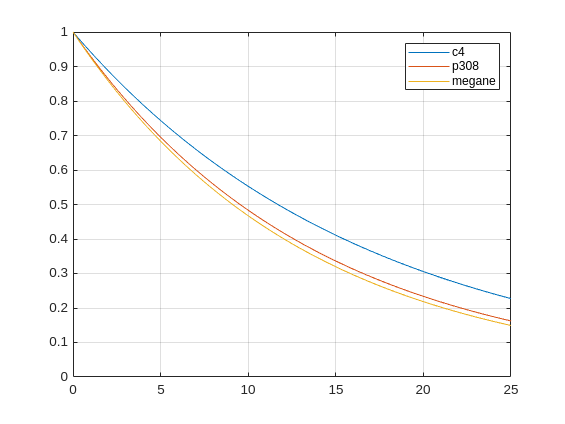

ys = [exp(c4fitted.c * x_age); exp(p308fitted.c * x_age); exp(meganefitted.c * x_age)];
plot(x_age,ys);
legend("c4", "p308", "megane")
ylim([0, 1])
grid on

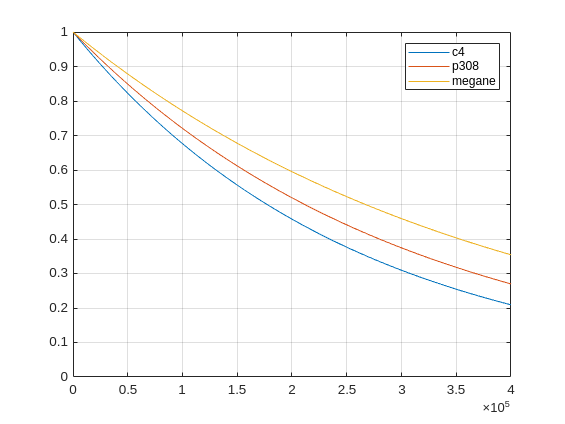


x_km = 0:400000;
ys = [exp(c4fitted.b * x_km); exp(p308fitted.b * x_km); exp(meganefitted.b * x_km)];
plot(x_km,ys);
legend("c4", "p308", "megane")
ylim([0, 1])
grid on

The upper of these plots shows that the Citröen C4 holds its value best as a function of age (years), but it hold its relative value worst as a function of kilometers driven.

## How good is the fit?

The model with normalized prices and both km and age has the highest R² value, but its not impressively high. One parameter which could have a big impact is the transmission type, as automatic transmissions tend to cost more. Fitting with automatic transmission configurations removed.

c4 = c4(find(not(string(c4.Transmission) == 'Automatisk')), :);
[c4fittedman, c4gofman] = fitcar(c4)

c4fittedman =      General model:
     c4fittedman(km,age) = exp(b*km + c*age)
     Coefficients (with 95% confidence bounds):
       b =  -3.904e-06  (-5.46e-06, -2.347e-06)
       c =    -0.05657  (-0.08182, -0.03132)

c4gofman = struct with fields:
           sse: 0.030095
       rsquare: 0.78776
           dfe: 14
    adjrsquare: 0.77261
          rmse: 0.046365


R² went from 0.737 to 0.79, a significant increase. What could explain the remaining error? There is still one advert with an older engine type, and the trim levels are different across adverts. Geographical differences could maybe also change the prices. Also, there is one advert which is particularly cheap according to the model. Checking in later, this listing was sold, confirming the models prediction that this was a very good deal.

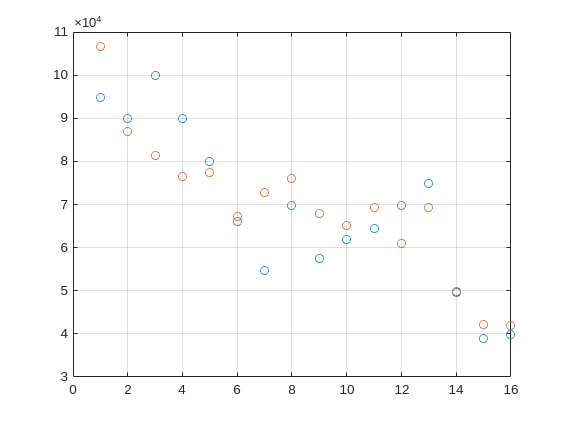

row = 1:size(c4, 1);

%sort c4 in km
c4 = sortrows(c4, "Kilometers", "ascend");

modelled_prices = c4.PriceNew .* exp(c4fittedman.b * c4.Kilometers + c4fittedman.c * c4.Age);
actual_prices = c4.Price;

plot(row, [actual_prices, modelled_prices], 'o');
grid on

The plot here shows the listing prices in blue, and a corresponding orange point which is the models prediction of what the asking price should be, as a function of new price, age and kilometers driven. Points number 7 are particularly cheap as compared to the model price suggestion. This car was sold already at the time of this analysis.

## Find best deal

**VOD **is my metric for the listing price subtracted from the modelled price. The unit is kroner. A positive number of 1000 means the value of the purchase is worth a 1000 kroner more than what you pay.

%valueofdeal
c4.vod = c4.PriceNew .* exp(c4fitted.b * c4.Kilometers + c4fitted.c * c4.Age) - c4.Price;
c4 = sortrows(c4, "vod", "descend");
c4([1:4, end-4:end], ["Make", "Model", "Price", "Tax","Kilometers", "Age", "vod"])

ans = 9×7 table
       Make        Model     Price    Tax     Kilometers     Age        vod  
    ___________    ______    _____    ____    __________    ______    _______

    {'Citroën'}    {'C4'}    54700    1040     1.47e+05     9.8333      16002
    {'Citroën'}    {'C4'}    94800    1860        65990     8.9167     9315.3
    {'Citroën'}    {'C4'}    57500    1860     1.68e+05     11.833     8138.4
    {'Citroën'}    {'C4'}    69700    1860     1.48e+05       9.25     4375.3
    {'Citroën'}    {'C4'}    89900    1040        93000     8.3333    -5061.5
    {'Citroën'}    {'C4'}    74900    1860     1.85e+05     8.3333    -7223.5
    {'Citroën'}    {'C4'}    69800    1040     1.74e+05     8.0833     -10240
    {'Citroën'}    {'C4'}    89900    1040 

The table shows, that an expensively listed car (number 2) can be a good deal, if it has very few kilometers. This car will however suffer from a lot of depreciation, and will not figure in the top when calculating cost of owning over time.

## Cost of owning over time

What is the cost, if the car cost 300kr a month in insurance, 1 kr. pr. km in maintenance, as well as the depreciation in value of the car based on the model, and tax? Renting out the car on Gomore is considered as well, using a conservative figure of 33% of earning potential as stated by Gomore themselves. Ownership period is set to three years and 20000 km driven.

% cost of ownership
% 3 years tax + 36 months insurance (300) and renting income (0.33 * 3120)
% + maintenance (1 kr / km + depreciation
c4.coo = 3*c4.Tax + (3*12) * (300 - 0.33 * 3120) + 20000 + (c4.Price - c4.PriceNew .* exp(c4fittedman.b .* (c4.Kilometers + 20000) + c4fittedman.c .* (c4.Age + 3)));
c4 = sortrows(c4, "coo");
c4(1:8, ["Make", "Model", "Price", "Tax","Kilometers", "Age", "vod", "coo"])

ans = 8×8 table
       Make        Model     Price    Tax     Kilometers     Age        vod        coo  
    ___________    ______    _____    ____    __________    ______    _______    _______

    {'Citroën'}    {'C4'}    54700    1040     1.47e+05     9.8333      16002    -5169.3
    {'Citroën'}    {'C4'}    38900    1040      2.3e+05      10.25     2096.7       2809
    {'Citroën'}    {'C4'}    57500    1860     1.68e+05     11.833     8138.4     3861.1
    {'Citroën'}    {'C4'}    39900    1040     2.44e+05     8.9167     970.03       4026
    {'Citroën'}    {'C4'}    49700    1040     2.27e+05          8    -1048.3     7695.1
    {'Citroën'}    {'C4'}    62000    1040     1.69e+05     8.3333     1547.5     8070.1

Had I been quick and bought the best deal car, I might have left my three year ownership with a bit of money for fuel (5169 kr). A few remaining options are still very cheap considering everything, but unless I'm very good at advertizing the car for rental, I should not expect to actually earn anything. Still, owning a car may have value not quantifiable in "kroner og ører", that is, you can't put a price on everything.

The Citröen C4 1.6 BlueHDI 100 with an asking price of 38900 kr. seems like a promising candidate for an economical ownership.